# Replicating an investment strategy

## How to use this live script

As usual, in this executable notebook (Live Editor) you have a logical track of the work, not a full pipeline but a trace, with working code snippets, some (non-binding) method suggestions, etc. (When it comes to data modeling, there is almost never a "one size fits all", thus you can take various ways to solve the problem.)

So feel free to take this code as a draft, change it, even significantly, following your modeling vision. Feel free to explore data and methods and gain experience (yes, even getting it wrong and getting results you don't like - it's quite normal in real applications). You will find some "*HINTS*": they are just suggestions for you. Remember: experimenting with data - that's the purpose of this Machine Learning Lab.

We will use a dataset called "InvestmentReplica" and is conveniently saved as a .mat file, even if you have also the corresponding .xls file ("InvestmentReplica.xlsx)" that you can use to download data from Bloomberg, in case you have access to a Bloomberg terminal.

## Goal: investment replica

We consider the following problem:

- There is a secret portfolio, a financial black-blox, which publicly reports its returns on a regular basis (say weekly, monthly, daily);

- We do not know either which instruments the portfolio contains or what weight each instrument has;

- We do know the vast investments vehicles available in the markets, such as bonds and stocks, ETFs, Funds, Futures contracts.

So even if we don't know how the black-box processes the input information, that is, the returns of a large variety of investment instruments, we can see the output of the black-box, ie the time series of returns generated by the black-box: our goal is to guess what the inside of the black box looks like.

This means extracting information about latent variables or functions and structural parameters from observed information.

This is a dataset of financial data, representing:

- **The HFRX Index, an index of hedge funds** - see [https://www.hfr.com/indices](https://www.hfr.com/indices) - for those with little or no exposure to Hedge Funds, see [https://en.wikipedia.org/wiki/Hedge_fund](https://en.wikipedia.org/wiki/Hedge_fund); 

- **The MSCI World Index (Global Developed Equities)**, see [https://www.msci.com/acwi](https://www.msci.com/acwi);

- **The MSCI World All Country Index (Global Equities, both Developed and Emerging)**, see [https://www.msci.com/acwi](https://www.msci.com/acwi);

- **The Barclays Bloomberg Global Aggregate Bond Index (Global Bonds, Developed and Emerging, Govt and Corporate)**, see [https://www.bloomberg.com/quote/LEGATRUU:IND](https://www.bloomberg.com/quote/LEGATRUU:IND);

- A broad range of **Futures contracts on equity indices, benchmark bonds, currencies, commodities**.

More specifically, these are the Futures at our disposal:

- RX1 = Bund (10 Yrs Ger)

- CO1 = Brent (Oil)

- DU1 = Schatz (2yrs Gvt Ger)

- ES1 = S&P 500 ( US Equity)

- GC1 = Gold

- LLL1 = MSCI Emerging Markets (EM Equity)

- NQ1 = Nasdaq 100 (Tech Equity)

- TP1 = Topix (Jap. Equity)

- TU2 = 2Yrs US Treasury (US Gvt)

- TY1 = 10Yrs US Treasury (US Gvt)

- VG1 = Eurostoxx 50 (EU Equity)

Other info on this dataset:

- From Bloomberg;

- Weekly data in local currency;

- In the original, raw format (but mostly clean);

- Period = Oct-2007/Apr-2021.

#### "Who replicates what?"

To do a challenging workout with index replication and exploring this kind of anaklytics, we will try to replicate a "monster index" (that we will build ourselves) consisting of tens of thousands of securities at the micro-level. It's a true otherwise non-investable black-box, which practically combines a large part of the stock market, bond and the world of hedge fund, in a multi-currency fashion.

In order to create our clone, we will use Futures contracts (long-short, possibly using leverage). They are cheap (see [https://www.cmegroup.com/trading/equity-index/report-a-cost-comparison-of-futures-and-etfs.html#](https://www.cmegroup.com/trading/equity-index/report-a-cost-comparison-of-futures-and-etfs.html#)), liquid, easy-to-use, and they cover...almost everything (see: [https://www.marketwatch.com/tools/futures).](https://www.marketwatch.com/tools/futures).) We will use a subset of popular Futures contracts. For those with little exposure to finance, see [https://www.cmegroup.com/education/files/a-traders-guide-to-futures.pdf.](https://www.cmegroup.com/education/files/a-traders-guide-to-futures.pdf.)

Of course, alternatively you might replicate:

- The HFRX Hedge Fund Index using Futures contracts (long-short, possibly using leverage);

- The HFRX Hedge Fund Index using MSCI World, MSCI World AC, Barclays Bloomberg Global Aggregate Bond Index, since there are liquid ETFs on indices (or very similar indices);

- We might also replicate MSCI World, MSCI World AC, Barclays Bloomberg Global Aggregate Bond Index using futures contracts.

#### *Load data*

close all
clc
path = '/Users/veron/OneDrive - Politecnico di Milano/fintech/Lab/BusinessCase4_Zenti/InvestmentReplica.mat';
load(path)

The .mat file includes both single variables and a table (for me, sometimes one type of data is more convenient, sometimes the other).

## A short data exploration

We begin with plot the time series of HFRX Index (Hedge Funds) vs global equities (MSCI World AC) and vs  Barclays Bloomberg Global Aggregate Bond Index.

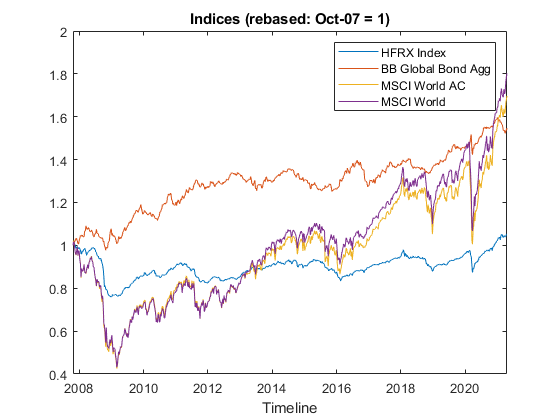

figure
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

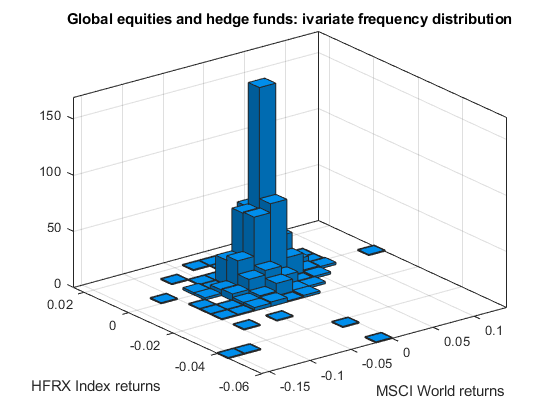

figure
histogram2(price2ret(MXWO),price2ret(HFRXGL))
xlabel('MSCI World returns')
ylabel('HFRX Index returns')
title('Global equities and hedge funds: ivariate frequency distribution')

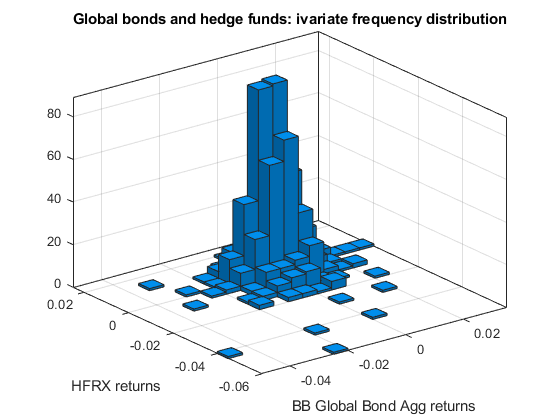


figure
histogram2(price2ret(LEGATRUU),price2ret(HFRXGL))
xlabel('BB Global Bond Agg returns')
ylabel('HFRX returns')
title('Global bonds and hedge funds: ivariate frequency distribution')

Let's create the "Monster Index": an weighted index (you specify the weights) made of of MSCI World AC, Barclays Bloomberg Global Aggregate, and HFRX...

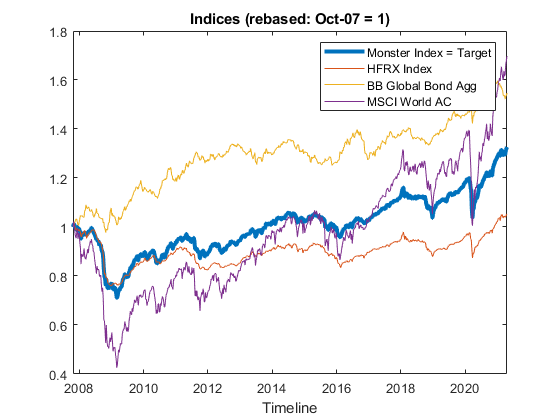

% Synthetic target weights
wHFRXGL = 0.5; 
wMXWO = 0.25;
wLEGATRUU = 0.25;

% Building the target
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

figure
p = plot(XTab.Date,target,'DisplayName','Monster Index = Target');
p.LineWidth = 3;
hold on;
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

Let's understand the shape of the distribution of our target return: many models are based on the hypothesis of normality, and it is good to know how distant we are.

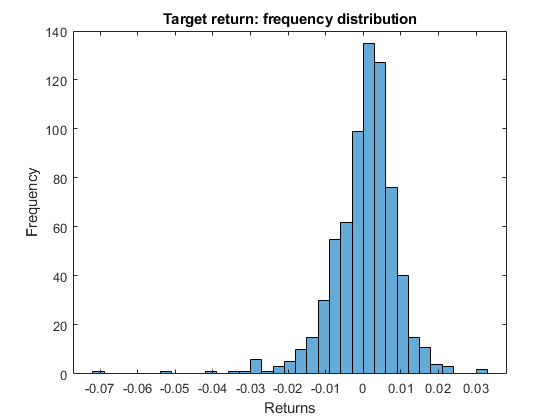

figure
histogram(y)
title('Target return: frequency distribution')
ylabel('Frequency')
xlabel('Returns')

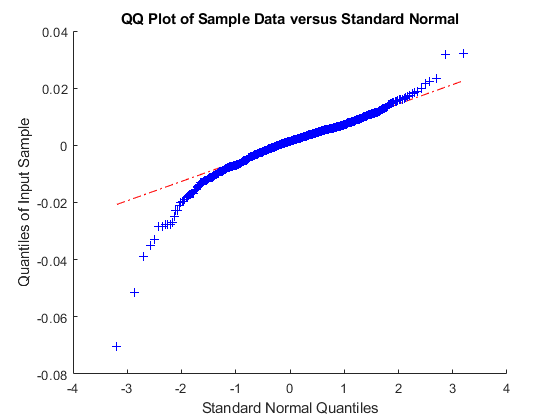

figure
qqplot(y)

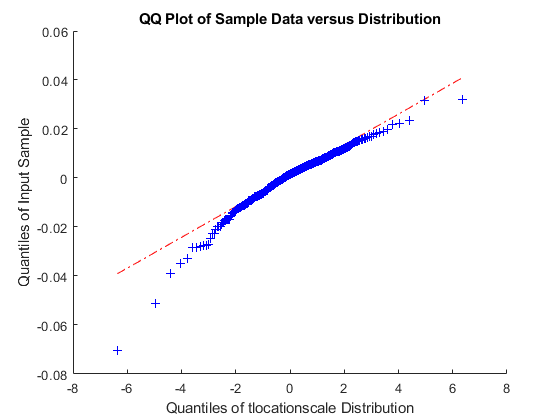

figure
qqplot(y, makedist("tLocationScale"))

Compute the returns for the Futures contracts. If you look at the time series, they have heterogeneous paths, so it' intuitive that they can be of help, if we want to replicate complex assets like the "Monster Index"

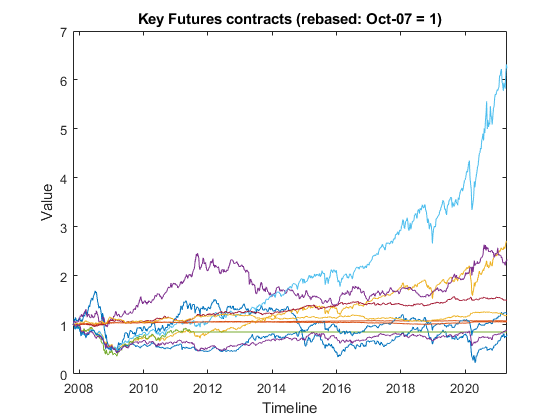

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(XTab.Date, ret2price(X))
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')

You might want have an idea of correlation among variables, both linear and rank-correlation (it might be useful for features selection):

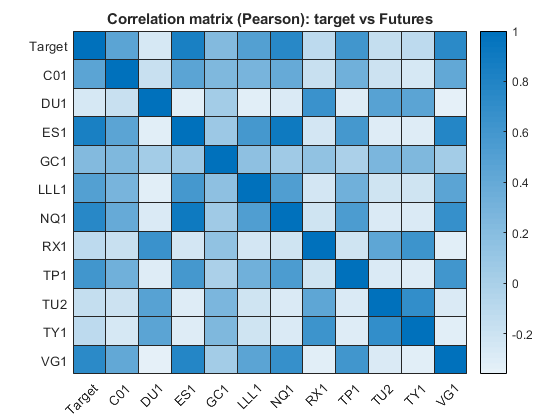

figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Pearson'));
h.Title = 'Correlation matrix (Pearson): target vs Futures';

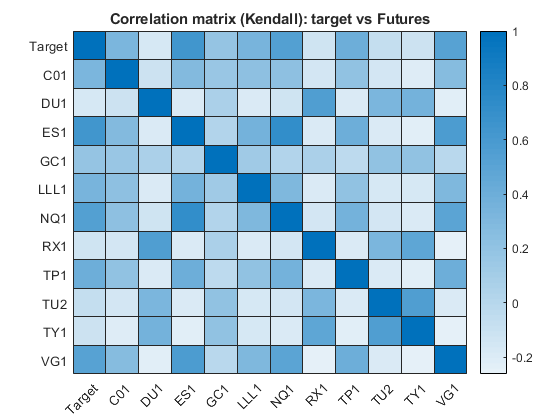

figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Kendall'));
h.Title = 'Correlation matrix (Kendall): target vs Futures';

We want inspect also time dependencies.

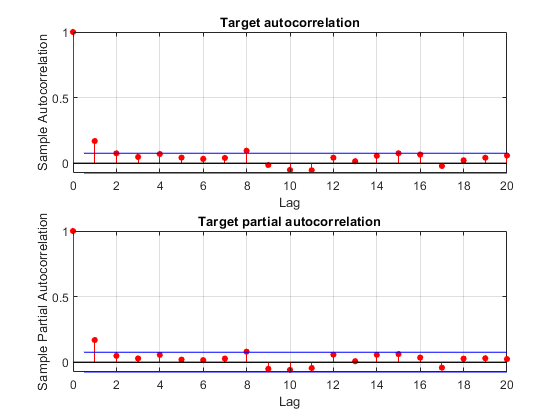

figure
subplot(2,1,1)
autocorr(y)
title('Target autocorrelation')
subplot(2,1,2)
parcorr(y)
title('Target partial autocorrelation')

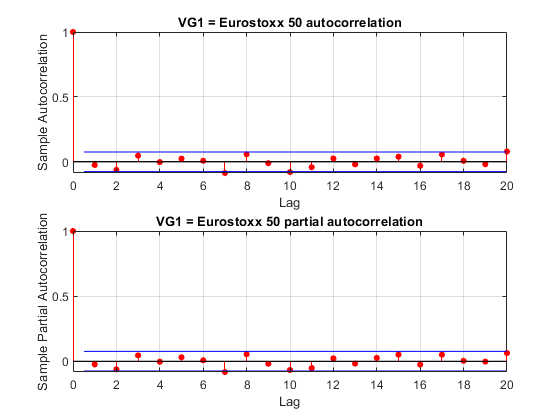

figure
subplot(2,1,1)
autocorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 autocorrelation')
subplot(2,1,2)
parcorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 partial autocorrelation')

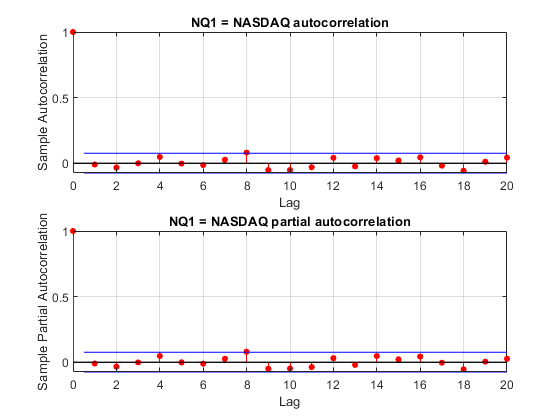

figure
subplot(2,1,1)
autocorr(price2ret(NQ1))
title('NQ1 = NASDAQ autocorrelation')
subplot(2,1,2)
parcorr(price2ret(NQ1))
title('NQ1 = NASDAQ partial autocorrelation')

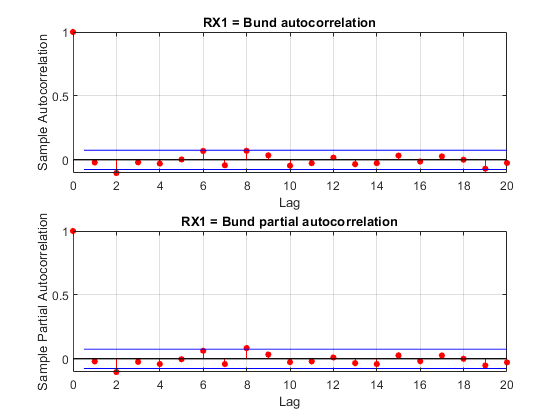

figure
subplot(2,1,1)
autocorr(price2ret(RX1))
title('RX1 = Bund autocorrelation')
subplot(2,1,2)
parcorr(price2ret(RX1))
title('RX1 = Bund partial autocorrelation')

## Developing a replica model

### Partion data

Since we are dealing with a phenomenon that develops over time, with time dependencies (see above), and must be dynamically tested, we slightly change the approach of creating and testing the model. The usual approach used with static or cross-sectional data doesn't make sense here.

With time series we'll use a backtest approach:

- in time t we define a rolling window of length K used for training and cross-validation (here we'll use a k-fold cross validation approach);

- we will use our estimated model out-of-sample, on unseen data, in order to predict from t to t+Horizon (Horizon will be = 1 here, but you can have longer horizons); 

- we will roll forward our sample, using this step-by-step estimation/prediction approach;

- we will judge the model on the prediction on unseen data - ie out-of-sample.

The backtest approach with financial data it is never sure: the financial markets are constantly changing. Our model can be meaningless if the world changes enough...

Before that  we select a sample to do some model exploration - particularly useful here, for educational purposes.

X_ME = X(1:350, :);   % Model Exploration set - independent variabiles
y_ME = y(1:350, :);   % Model Exploration set - response variabile
Date_ME = XTab.Date(1:351, :); % Model Exploration set - dates

### Preliminary model exploration

Let's do some model exploration, aimed to understand the general behaviour the models, very useful for educational purposes.

Some obvious but useful considerations:

- A replication portfolio is however a financial portfolio, that is, a (mostly) linear combination of financial assets, ie sum(price(i)*quantity(i));

- We model returns, but again, the return on an investment portfolio is a linear combination of the returns on its constituent financial assets;

- We are interested in the coefficients of the linear combination, that is, **portfolio weights**, so it is natural to use a regression that explicitly gives us these weights;

- Differently said, here we are interested in the **structure**, rather than in the prediction itself (for example a Gaussian process regression or a neural network is a model oriented to pure prediction, and the structure is almost unusable for portfolio construction purposes).

As always, it is good to start with the quick & dirt simplest ideas, so let's think about standard linear regression.

You might want to use the **Regression Learner App** to get a quick idea of the behavior of the models. (For educational needs, I do not use the Regression Learner App today, because I have to show you some things in more detail.)

Let's do a standard linear regression, without intercept.

This is an **in-sample estimate**, having all the history available, so don't rely too much on the results in terms of fit (out-of-sample prediction is another story...).

What I want to point out is how the regression coefficients behave with various models.

#### Standard linear regression (OLS)

b = regress(y_ME,X_ME)

b =     0.0330
   -0.5025
    0.1506
    0.0251
    0.0036
    0.0158
    0.1041
    0.0494
    0.1552
    0.1808


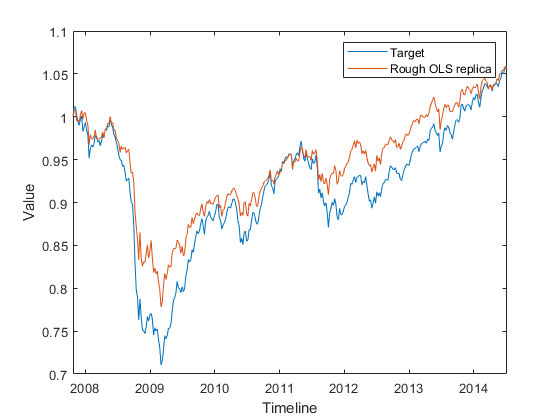

replRetOLS = X_ME*b; % compute portfolio returns using regression coefficients as weights
repOLS = ret2price(replRetOLS); % from returns to levels

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,repOLS,'DisplayName','Rough OLS replica');
xlabel('Timeline')
ylabel('Value')
legend
hold off;

#### Gross exposure?

Let's see the gross exposure ([https://www.investopedia.com/terms/g/gross-exposure.asp](https://www.investopedia.com/terms/g/gross-exposure.asp)).

If gross exposure exceeds 100%, it means the fund is using **leverage** - which is often the case (if interested on limits, how to compute it, and so on, see for example: [https://www.esma.europa.eu/sites/default/files/library/2015/11/10_788.pdf).](https://www.esma.europa.eu/sites/default/files/library/2015/11/10_788.pdf).) 

See the **Appendix at the end of the code**.

GrossExposure = sum(abs(b))

GrossExposure = 1.3061

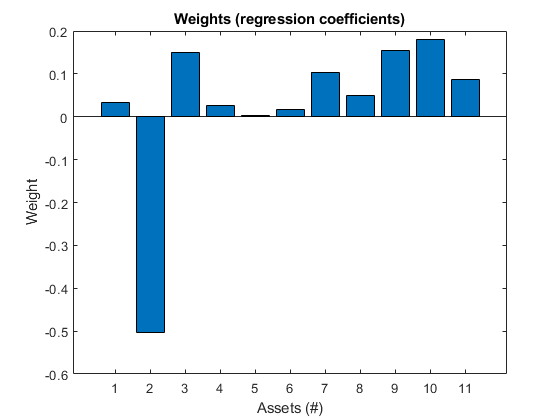

figure
bar(b)
title('Weights (regression coefficients)')
ylabel('Weight')
xlabel('Assets (#)')

### Digression: understanding the effect of sampling error on OLS estimates - Episode I

If you want to see how noisy are the estimates of the regression coefficients you can use a** bootstrap approach,** a (powerful) resampling technique - on resampling techniques see: [https://it.mathworks.com/help/stats/resampling-techniques.html?s_tid=CRUX_lftnav.](https://it.mathworks.com/help/stats/resampling-techniques.html?s_tid=CRUX_lftnav.) On bootstrap see Capther 7 of Elements of Statistical Learning: [https://web.stanford.edu/~hastie/ElemStatLearn/.](https://web.stanford.edu/~hastie/ElemStatLearn/.) Strongly suggested. (You can download it for free, legally).

Using the bootstrap we can get the empirical distribution of regression coefficients and a probability interval for them.

myRegression = @(predictor,response)regress(predictor,response); % create a function handle
nboot = 1e3; % number of resamples
bootb = bootstrp(nboot,myRegression,y_ME, X_ME); % distribution of regression coefficients
CIb = prctile(bootb, [2.5 97.5])' % C.I. of regression coefficients (prob = 5%)

CIb =     0.0098    0.0562
   -0.9822   -0.0930
    0.0848    0.2186
    0.0038    0.0522
   -0.0267    0.0329
   -0.0386    0.0684
    0.0047    0.2078
    0.0318    0.0660
   -0.2819    0.6417
    0.0602    0.2907


We inspect the frequency distribution of regression coefficients - here is for VG1 = Eurostoxx 50.

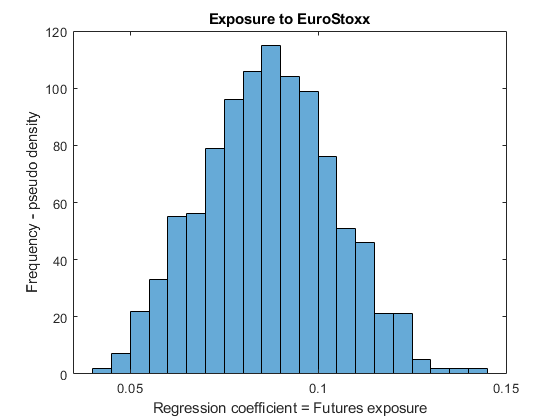

figure
histogram(bootb(:,11))
title('Exposure to EuroStoxx')
xlabel('Regression coefficient = Futures exposure')
ylabel('Frequency - pseudo density')

## Ridge, lasso, and elastic net regularization

Ridge, lasso, and elastic net regularization are all methods for estimating the coefficients of a linear model while penalizing large coefficients. The type of penalty depends on the method.

**Lasso** ([https://it.mathworks.com/help/stats/lasso.html](https://it.mathworks.com/help/stats/lasso.html)) is a regularization technique for performing linear regression. Lasso includes a penalty term that constrains the size of the estimated coefficients. Therefore, it resembles [ridge regression](https://it.mathworks.com/help/stats/ridge-regression.html). Lasso is a *shrinkage estimator*: it generates coefficient estimates that are biased to be small. Nevertheless, a Lasso estimator can have smaller mean squared error than an ordinary least-squares estimator when you apply it to new data. If the features have high correlation, the Lasso will only select one of them - which is not bade if you search an investment clone and want to minimize trading.

**Ridge** regression ([https://it.mathworks.com/help/stats/ridge.html](https://it.mathworks.com/help/stats/ridge.html)) is a method for estimating coefficients of linear models that include linearly correlated predictors (which is often the case, remember the correlation matrix above).

Unlike ridge regression, as the penalty term increases, Lasso sets more coefficients to zero. This means that the Lasso estimator is a smaller model, with fewer predictors. As such, lasso is an alternative to [stepwise regression](https://it.mathworks.com/help/stats/stepwise-regression.html) and other model selection and dimensionality reduction techniques.

**Elastic net** is a related technique. Elastic net is **a hybrid of ridge regression and Lasso regularization**. Like lasso, elastic net can generate reduced models by generating zero-valued coefficients. Empirical studies have suggested that the elastic net technique can outperform Lasso on data with highly correlated predictors.

basically, we use Lasso to:

- Reduce the number of predictors in a regression model;

- Identify important predictors;

- Select among redundant predictors;

- Produce shrinkage estimates with potentially lower predictive errors than ordinary least squares.

#### Lasso Regression

Remember, it still in-sample model exploration...

First, partition the data into 5 folds. In each fold, the software uses 4/5th of the data for training and unseen 1/5th of the data for validation.

You must choose the hyperparameter lambda, the regularization coefficient, and the two main options are;

- `Lambda` value with the minimum MSE = better fit;

- Largest `Lambda` value such that MSE is within one standard error of the minimum MSE = more robust (greater shrinkage towards zero).

You might want to do a grid search on Lambda (like we did with the Early Warning/Anomaly Detection exercise).

warning off
[bLasso,fitinfo] = lasso(X_ME,y_ME,'CV',5, 'Intercept',false);

Error using internal.stats.parseArgs (line 42)
Invalid parameter name: Intercept.

Error in lasso (line 262)
     = internal.stats.parseArgs(pnames, dflts, varargin{:});

warning on

Visually examine the cross-validated error of various levels of regularization.

lassoPlot(bLasso,fitinfo,'PlotType','CV');
legend('show')

The plot below shows the nonzero coefficients in the regression for various values of the `Lambda` regularization parameter. Larger values of `Lambda` appear on the left side of the graph, meaning more regularization, resulting in fewer nonzero regression coefficients.

The dashed vertical lines represent the `Lambda` value with minimal mean squared error (on the right), and the `Lambda` value with minimal mean squared error plus one standard deviation (more robust choice)

The upper part of the plot shows the degrees of freedom (df), meaning the number of nonzero coefficients in the regression, as a function of Lambda.

lassoPlot(bLasso,fitinfo,'PlotType','Lambda','XScale','log');
ylabel('Value of the regression coefficients')
lam = fitinfo.IndexMinMSE; %Lambda such that MSE is min
fitinfo.MSE(lam)
bLasso = bLasso(:,lam)
GrossExposure = sum(abs(bLasso))
figure
bar(bLasso)
title('Weights (Lasso regression coefficients)')
ylabel('Weight')
xlabel('Assets (#)')
replicaRetLasso = X_ME*bLasso;
replicaLasso = ret2price(replicaRetLasso);

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,replicaLasso,'DisplayName','LASSO replica');
legend
xlabel('Timeline')
ylabel('Value')
hold off;

Try a stronger penalization, using a larger Lambda.

warning off
[bLasso2,fitinfo] = lasso(X_ME,y_ME,'CV',5, 'Intercept',false);
warning on

lam = fitinfo.Index1SE; % Lambda such that MSE is within 1 SE of min MSE
fitinfo.MSE(lam)
bLasso2 = bLasso2(:,lam)
GrossExposure = sum(abs(bLasso2))
figure
bar(bLasso2)
title('Weights (Lasso regression 2 coefficients)')
ylabel('Weight')
xlabel('Assets (#)')
replicaRetLasso2 = X_ME*bLasso2;
replicaLasso2 = ret2price(replicaRetLasso2);

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,replicaLasso2,'DisplayName','Lasso 2 replica');
legend
xlabel('Timeline')
ylabel('Value')
hold off;

#### Digression on sampling/estimation error - Episode II

Same as above - just to understand.

But you can also use bootstrap estimate to get robust estimators (e.g. you take the median).

warning off
myRegression = @(predictor,response)LassoReg(predictor,response); % create a function handle
nboot = 1e3; % number of resamples
bootb = bootstrp(nboot,myRegression,X_ME, y_ME); % distribution of regression coefficients
CIb = prctile(bootb, [2.5 97.5])' % C.I. of regression coefficients (prob = 5%)
warning on
figure
histogram(bootb(:,11))
title('Exposure to EuroStoxx')
xlabel('Regression coefficient = Futures exposure')
ylabel('Frequency - pseudo density')

***HINT***: try using the mean of bootstrapped regression coefficients for the replica, see the difference.

#### Elastic Net

It's an hybrid: elastic net is the same as Lasso when *α* = 1. Basically there is a penalty term that allows interpolating between the *L*1 norm and the squared *L*2 norm. As *α* shrinks toward 0, elastic net approaches [`ridge`](https://it.mathworks.com/help/stats/ridge.html) regression. See: [https://it.mathworks.com/help/stats/lasso.html#mw_edfef154-77aa-4a02-b3e1-7bd7a4a8378b](https://it.mathworks.com/help/stats/lasso.html#mw_edfef154-77aa-4a02-b3e1-7bd7a4a8378b). 

Weight of lasso (*L*1) versus ridge (*L*2) optimization: specified as the comma-separated pair consisting of `'Alpha'` and a positive scalar value in the interval `(0,1]`. The value `Alpha = 1` represents Lasso regression, `Alpha` close to `0` approaches [ridge regression](https://it.mathworks.com/help/stats/ridge-regression.html), and other values represent elastic net optimization.

warning off
[bENet,fitinfo] = lasso(X_ME,y_ME,'Alpha',0.5,'CV',5, 'Intercept',false);
warning on
lassoPlot(bENet,fitinfo,'PlotType','CV');
legend('show')
lam = fitinfo.IndexMinMSE; %Lambda such that MSE is min
fitinfo.MSE(lam)
bENet = bENet(:,lam)
GrossExposure = sum(abs(bENet))
figure
bar(bENet)
title('Weights (Elastic Net regression coefficients)')
ylabel('Weight')
xlabel('Assets (#)')
replicaRetENet = X_ME*bENet;
replicaENet = ret2price(replicaRetENet);

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,replicaENet,'DisplayName','Elastic Net replica');
legend
xlabel('Timeline')
ylabel('Value')
hold off;

Try a more parsimonious Elastic Net;

warning off
[bENet2,fitinfo] = lasso(X_ME,y_ME,'Alpha',0.5,'CV',5, 'Intercept',false);
warning on
lam = fitinfo.Index1SE;
fitinfo.MSE(lam)
bENet2 = bENet2(:,lam)
GrossExposure = sum(abs(bENet2))
figure
bar(bENet2)
title('Weights (Elastic Net 2 regression coefficients)')
ylabel('Weight')
xlabel('Assets (#)')
replicaRetENet2 = X_ME*bENet2;
replicaENet2 = ret2price(replicaRetENet2);

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,replicaENet2,'DisplayName','Elastic Net 2 replica');
legend
xlabel('Timeline')
ylabel('Value')
hold off;

#### Towards Ridge regression

Try Alpha close to 0.

warning off
[bRidge,fitinfo] = lasso(X_ME,y_ME,'Alpha',0.1,'CV',5, 'Intercept',false);
warning on
lassoPlot(bRidge,fitinfo,'PlotType','CV');
legend('show')
lam = fitinfo.Index1SE;
bRidge = bRidge(:,lam)
GrossExposure = sum(abs(bRidge))
figure
bar(bRidge)
title('Weights (Ridge regression coefficients)')
ylabel('Weight')
xlabel('Assets (#)')
replicaRetRidge = X_ME*bRidge;
replicaRidge = ret2price(replicaRetRidge);

figure
plot(Date_ME,ret2price(y_ME),'DisplayName','Target');
hold on;
plot(Date_ME,replicaRidge,'DisplayName','Ridge regression replica');
legend
hold off;

***HINT***: have a look at the Regression Learner App (it works very similar to the Classification Learner App we have already used).

You can also try Stepwise Regression - see [https://it.mathworks.com/help/stats/stepwiselm.html](https://it.mathworks.com/help/stats/stepwiselm.html). 

For high dimensional data, you can use `fitrlinear`, that allows you to optimize hyperparameters automatically (computationally intensive) - see [https://it.mathworks.com/help/stats/fitrlinear.html](https://it.mathworks.com/help/stats/fitrlinear.html). 

## Backtesting the model

Let's do the real job: we train/cross-validate and forecast moving forward step-by-step.

We use coefficients that we estimate in t to form a portfolio that will try to replicate our target in (t, t + Horizon], here Horizon = 1.

(In the code below just change the specification of the model and to test different ones.)

rollingWindow = 156; % in weeks (52 = 1Y, 104 = 2Y...)
i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
    [b,fitinfo] = lasso(X(startSample:endSample,:),y(startSample:endSample),'Alpha',0.85,'CV',5, 'Intercept',false);
%   lam = fitinfo.IndexMinMSE; % lambda corresponding to MinMSE (better fit)
%   lam = fitinfo.Index1SE; % lambda 1SE away from MinMSE (more robust)
    lam = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2); % lambda half-way between MinMSE and 1SE away from MinMSE
    b = b(:,lam);
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b'];
    r = X(endSample + 1,:)*b;
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again

### Some financial statistics

#### Tracking Error Volatility (TEV)

Tracking Error = Excess Return = difference between target performance and replica performance.

Tracking Error Volatility = (annualized) standard deviation of Tracking Error.

TE = rENet2 - y(rollingWindow + 1: end); % tracking error
TEV = std(TE)*sqrt(52)

#### Gross Total Return, and Excess Return (ER)

Even if it is normal for a replica to have a negative excess return,  let's see how negative it is, so we compute the annualized mean Excess Return.

logRClone = diff(log(ret2price(rENet2))); % ...much easier to compute annualized metrics from log-returns
logRTarget = diff(log(ret2price(y(rollingWindow + 1: end))));
logTE =  logRClone - logRTarget;
meanTRTarget = exp(mean(logRTarget)*52) - 1
meanTRClone = exp(mean(logRClone)*52) - 1
meanER = exp(mean(logTE)*52) - 1

#### **Information Ratio (IR)**

The information ratio is similar to the Sharpe Ratio: is a measurement of portfolio returns beyond the returns of a benchmark, compared to the volatility of those returns.

IR = meanER/TEV

#### Turnover

Sum of the absolute values ��of the difference in the weights between old and new portfolio, divided by 2; example: if you have just one asset, and sell it in order to buy another asset - a 100% switch - you have /| `-100% `|  + | +100% |)/2 = 100% which makes sense.

A turnover = 100% per annum means that you sell the entire portfolio.

Turnover = calcTurnover(bENet2); % weekly turnover
meanTurnover = mean(Turnover)*52 % average annual turnover

#### Trading costs (proxy)

A good approximation of explicit trading costs is given by turnover x transaction costs.

tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
meanTradingCosts = meanTurnover*tradingCosts

#### Net metrics (proxy)

Let's keep into account explicit trading costs, as a first rough approximation.

NetTR = meanTRClone - meanTradingCosts % transaction costs (hp: buyCosts=sellCost)
NetER = meanER - meanTradingCosts
NetIR = NetER/TEV

figure
plot(Date(rollingWindow+1:end),ret2price(y(rollingWindow + 1: end)),'DisplayName','Target');
hold on;
plot(Date(rollingWindow+1:end),ret2price(rENet2),'DisplayName','Replica');
legend
title('Clone vs target')
hold off;
figure
plot(Date(rollingWindow+2:end),GrossExposure+1); % add 1 for your collateral + margins
title('Leverage = Total gross exposure')
xlabel('Timeline')
ylabel('Gross exposure')
hold off;

***HINTS***: what you could do?

1) Try different linear models in the backtesting, testing:

- different rolling windows

- different rebalancing windows (every N weeks, eg 4 weeks, 12 weeks)

- different hyperparameters, eg `lambda`, `Alpha`.

2) Take into account some hypotetical VaR limits or leverage limits (so you should compute VaR, even a simple Historical Simulation or parametric VaR insiede the backtesting loop).

3) For the bravest, if you have already studied State Space models and the Kalman filter, I dare suggest: try using the Kalman filter.

More on this sub 3)...You might consider a linear multivariate Gaussian state-space model ([https://it.mathworks.com/help/econ/what-are-state-space-models.html](https://it.mathworks.com/help/econ/what-are-state-space-models.html).

We have one observable variable, ie target portolio return, which is a function of:

- an unobservable variable, the vector of weights;

- an observable variable, the vector of (candidate) asset returns.

Set:

*        y(t) *= target return from t-1 to t, scalar;

*        x(t)* = unknown weights, vector nAsset x 1

Now we can represent the using the following system of equations (State-Space Model)

*        x(t) *= *A*x(t*−1)+*B*u(t) *

*        y(t) *=*C(t)*x(t)*+*D*ε(t)*

where (reasonably):

A = identity matrix, i.e. w(i,t) = w(i,t-1) + random innovation;

B = diagonal matrix of unknown std.dev;

C(t) = returns of the Futures contracts, vector 1 x nAssets

D = volatility of target returns.

You can estimate the State-Space model using the Kalman filter (see: [https://it.mathworks.com/help/econ/what-is-the-kalman-filter.html#buzeyb_-1](https://it.mathworks.com/help/econ/what-is-the-kalman-filter.html#buzeyb_-1)) . On this topic, see: [https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1325190](https://papers.ssrn.com/sol3/papers.cfm?abstract_id=1325190). 

#### *Appendix - what can be done in the UCITS (MIFID) framework*

UCITS funds can offer leverage (in UCITS jargon also called "global exposure"). Even a lot of leverage.

Direct physical short selling is not permitted nor is borrowing other than on a temporary basis in order to bridge settlement mismatches between investor and fund transactions and is limited to 10% of NAV. However, leverage can be generated through the use of derivatives. Global exposure/leverage can be measured in one of two ways:

- **Commitment Approach**: A UCITS that does not extensively use derivatives nor uses complex derivatives can opt to measure leverage using the “commitment approach”. This approach looks at the market value of the asset underlying the derivative (which can be delta adjusted for options) and takes a simple aggregate of the absolute values of the underlying exposures (or notional values). Adjustments can be made for netting arrangements and contracts that are used for hedging purposes (risk reducing) do not need to be included in the calculation (subject to certain correlation criteria). Global exposure/ leverage up to 100%, i.e. a total gross market exposure of 200% of NAV, is permitted under the commitment approach. This means that max leverage is 2.

- **Value at Risk**: A UCITS may alternatively choose to measure leverage based on a so called "Advanced Risk Methodology" such as a Value at Risk (“VaR”) measure. This will be required for strategies that make extensive use of derivatives and/or use complex derivatives resulting in commitment from derivatives positions greater than 100% but may also be chosen by managers with long-only strategies. The regulations permit two types of VaR measure: absolute VaR and relative VaR. The absolute VaR limit depends on the risk profile of a fund but the maximum absolute VaR limit is 20% over a 20 day holding period based on a confidence interval of 99%. The relative VaR limit is twice the VaR of a derivative free benchmark. In this case the only limit is VaR, not leverage, that might be >>2.

Just to have a rough idea of what it means a monthly VaR Limit of 20%:

                                                                  VaRLimit_1M = 20% => 20% = sigma_1M*abs(norminv(0.01))

VarLimit_1M = 20;
sigma_1M = 20/abs(norminv(0.01)); % assuming a 99%-Gaussian VaR (totally wrong, but incredibly pop in the industry)
sigma_1Y = sigma_1M*sqrt(12) % annualized volatility

The following is a non-exhaustive list of product types that can be structured within a UCITS. Many alternative strategies have been launched as UCITS. The product opportunities in the alternative UCITS space are many: a) Traditional (long only) strategies (equity/ bond/money market/funds of funds); b) Exchange-traded funds; c) Structured products (index/structured/ guaranteed funds); d) Alternative strategies (equity/credit/ macro/relative value/multi-strategy/ event driven); e) Funds of alternative UCITS funds.

Possible in UCITS funds:

- Short positions through derivatives: Y

- Futures and options: Y

- Long/short: Y

- OTC derivatives: Y 

- Commodity exposure (through indices): Y

- Repos/reverse repos/stock lending: Y 

- Leverage: Y 

- Absolute return: Y

- Physical Shorting (equities, bonds, commosities): N 

- Commodity derivatives: N 

- Physical commodities: N

- Direct Real Estate/Private Equity/Private Debt: N

#### What if you have to reduce leverage?

Simplest working solution (even if you can use Quadratic Programming to find the feasibile set of weights that minimize TEV vs the over-leveraged porfolio..."much ado about nothing" in 99% of the situations..).

MaxLeverage = 1.8;
EffectiveMaxleverage = MaxLeverage - 1; % Collateral bonds and cash count...
YourBeta = [-0.8  1  0.2  -0.5];
CurrentLeverage = sum(abs(YourBeta))
YourNewBeta = (YourBeta/CurrentLeverage)*MaxLeverage
NewLeverage = sum(abs(YourNewBeta))

[](https://etda.libraries.psu.edu/files/final_submissions/8206)